clear all;
clc;

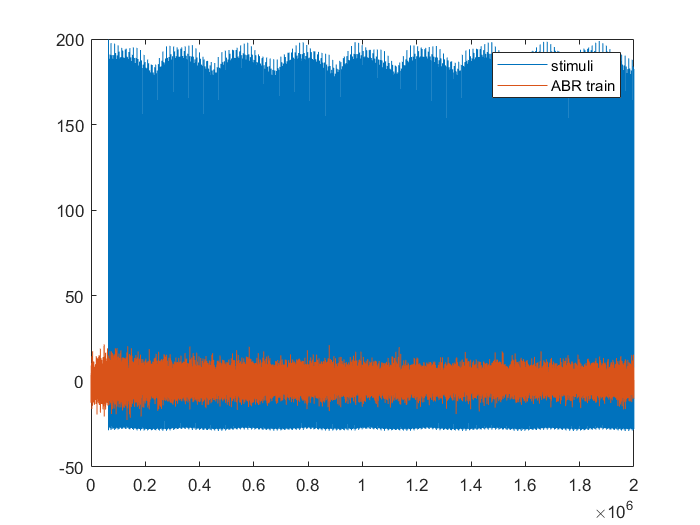

load ABR_rec.mat;
figure, plot(ABR_rec),legend('stimuli','ABR train');

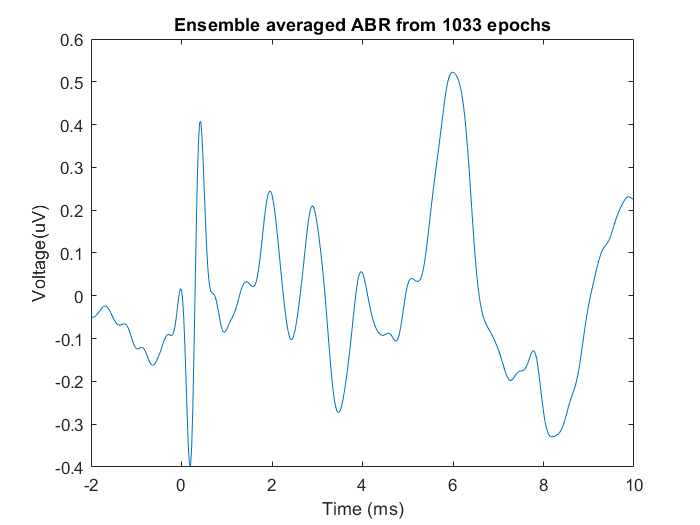

thresh = find(ABR_rec(:,1)>50);

j=1;
for i=1:length(thresh)-1
    if thresh(i+1)-thresh(i)>1
        stim_point(j,1)=thresh(i+1); 
        j=j+1;
    end
end

j = 0;
for i=1:length(stim_point) 
    j = j + 1;
    epochs(:,j) = ABR_rec((stim_point(i)-80:stim_point(i)+399),2);
end
ensmbl_avg = mean(epochs(:,(1:length(stim_point))),2);

figure,
plot((-80:399)/40,ensmbl_avg)
xlabel('Time (ms)'), ylabel('Voltage(uV)')
title(['Ensemble averaged ABR from ',num2str(length(epochs)),' epochs'])

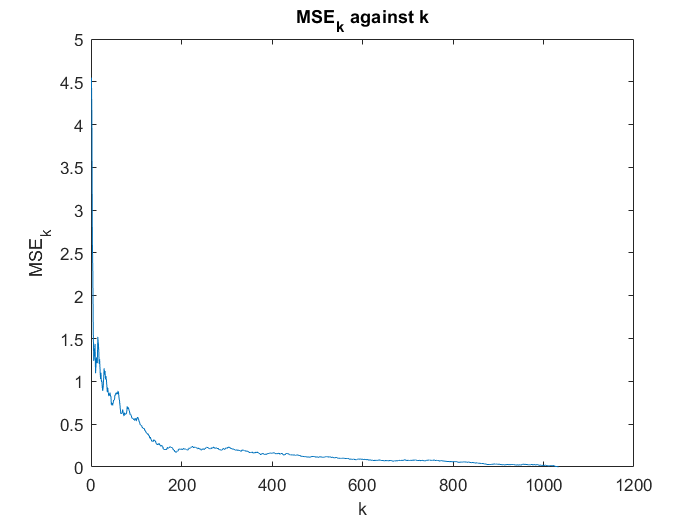

MSEk_vals=(1);
for r=1:length(stim_point)
    MSEk_vals(r)=CalcMSEk(480,r,ensmbl_avg,epochs);
end
plot(MSEk_vals)
xlabel('k')
ylabel('MSE_k')
title('MSE_k against k')

clear;
clc;
load ECG_rec.mat;
t=(0:length(ECG_rec)-1)/128;

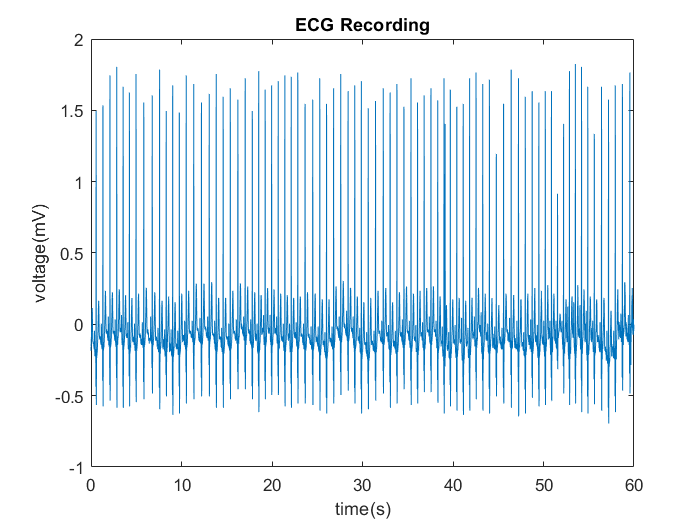

plot(t,ECG_rec)
title('ECG Recording')
xlabel('time(s)')
ylabel('voltage(mV)')

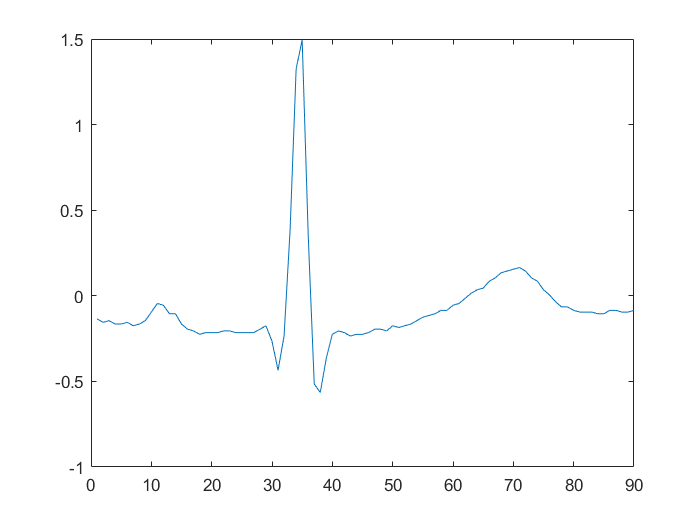

ECG_template=ECG_rec(40:129);
plot(ECG_template)

nECG=awgn(ECG_rec,5,'measured');

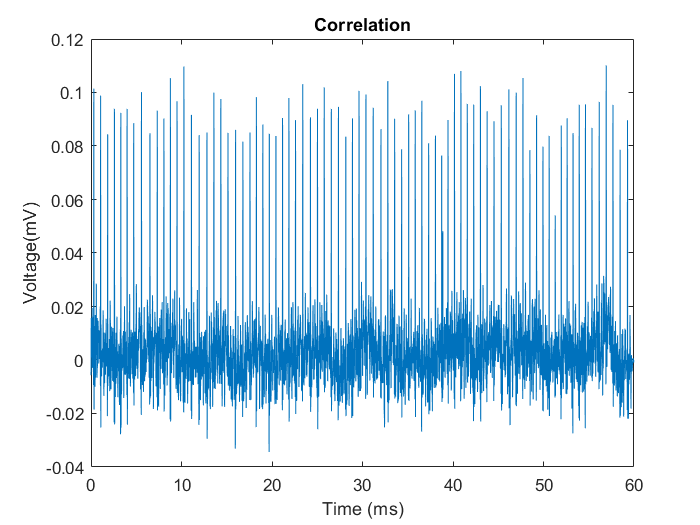


padding=ceil((length(ECG_rec)-length(ECG_template))/2);
ECG_template1=padarray(ECG_template, [0 length(ECG_rec)-length(ECG_template)], 0, 'post');
corr=xcorr(nECG,ECG_template1,'normalized');
corr=corr(1,floor(length(corr)/2):end);
num_samples=length(corr);
time=(0:num_samples-1)/128;
plot(time,corr)
xlabel('Time (ms)')
ylabel('Voltage(mV)')
title('Correlation')

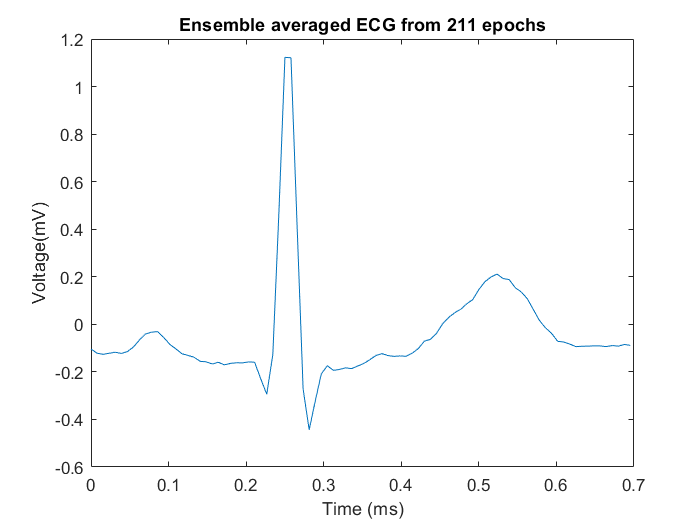

thresh = find(corr(1,:)>0.05);
stim_point=[1;1];
j=1;
for i=1:length(thresh)-1
    if thresh(i+1)-thresh(i)>0.05
        stim_point(j,1)=thresh(i+1); 
        j=j+1;
    end
end

j = 0;

for i=1:length(stim_point)
    j = j + 1;
    epochs(:,j) = nECG(1,(stim_point(i):stim_point(i)+89));
end

ensmbl_avg = mean(epochs,2);
num_samples = length(ensmbl_avg);
time = (0:num_samples-1)/128;
figure;
plot(time,ensmbl_avg);
xlabel('Time (ms)');
ylabel('Voltage(mV)');
title(['Ensemble averaged ECG from ',num2str(length(epochs)),' epochs'])

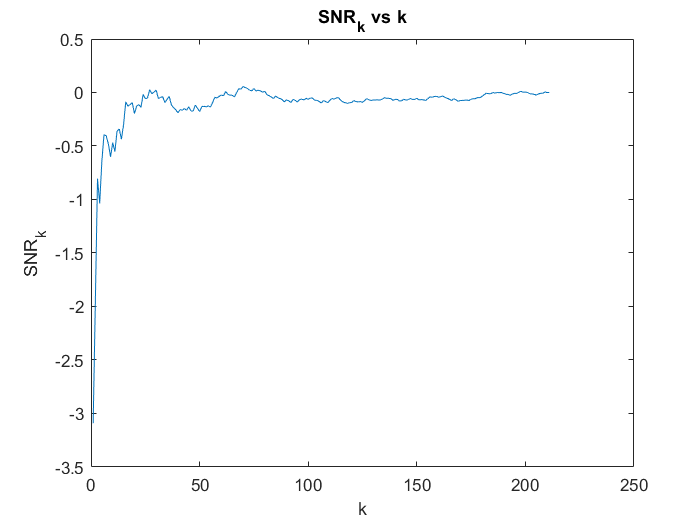

SNRs=[];
for i = 1:1:length(epochs)
    SNRs(i,1) = snr(ensmbl_avg, mean(epochs(:,1:i),2));
end
plot(SNRs)
xlabel('k')
ylabel('SNR_k')
title('SNR_k vs k')

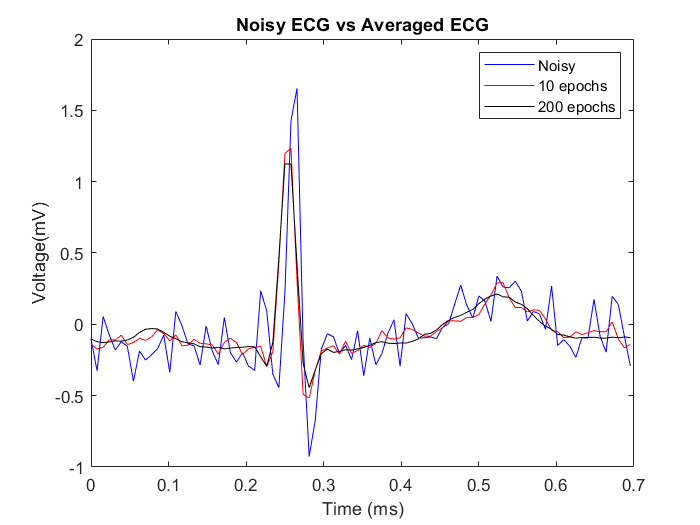

plot(time,epochs(:,3),'b',time,mean(epochs(:,1:10),2),'r',time,mean(epochs(:,1:200),2),'k')
xlabel('Time (ms)');
ylabel('Voltage(mV)');
legend('Noisy', '10 epochs', '200 epochs');
title('Noisy ECG vs Averaged ECG');

function MSEk = CalcMSEk(N,k,template,epochs)
    yk=mean(epochs(:,1:k),2);
    y=sum((template-yk).^2);
    MSEk=(y/N)^0.5;
end